# HomeWork n.1 2020/21

**COGNOME: PANICO**

**NOME: GENNARO**

**MATRICOLA: 0124002115**

## Corso di Calcolo Numerico  (CdS Informatica) - prof. G.Giunta, prof. A. Galletti

**(scadenza: 18 aprile 2021, ore 23:59)**

#### 1. definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete `funrif`;

Data la funzione $e^{-x} \cdot (sin(\frac {p \cdot x}{2}-\pi/2))^2 +  \frac {q}{1+3x^2}sin(2x)-5$ costruisco la funzione di riferimento sostituendo a "p" e "q",  rispettivamente il numero di caratteri del mio nome e del mio cognome, in questo modo implemento la funzione funrif esplicitamente senza l'uso di un m-file e evitando anche di dichiarare antecedentemente le variabili p e q.

%funrif in linguaggio MathLab
funrif =@(x) exp(-x).*(sin(((7*x)./2)-(pi/2))).^2+(6./(1+3*x.^2)).*sin(2*x)-5;

Dopodiché, considero la mia funrif, nell'intervallo posto in esempio ovvero [-4,-1] visualizzando il grafico della funzione tramite il comando** fplot **dandogli: un titolo(**title**); assegnado agli assi le lettere x e y per una maggiore chiarezza(**xlabel - ylabel**) e infine uso **grid on.**

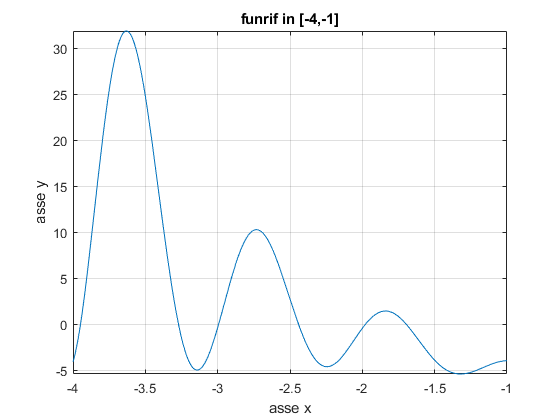

figure(1)
fplot(funrif,[-4 -1])
title('funrif in [-4,-1]')
xlabel('asse x')
ylabel('asse y')
grid on

Noto che la mia funzione di riferimento in tale intervallo d'esempio, non rispetta le condizioni richieste dalla traccia, ovvero in questo intervallo vi sono 6 zeri, 3 punti di massimo e 4 punti di minimo. Mi affido quindi a Matlab, usando il comando **fplot** senza però indicare l'intervallo di riferimento, in questo modo Matlab sceglie un intervallo da sé, permettondomi quindi di studiare al meglio l'andamento della funzione.

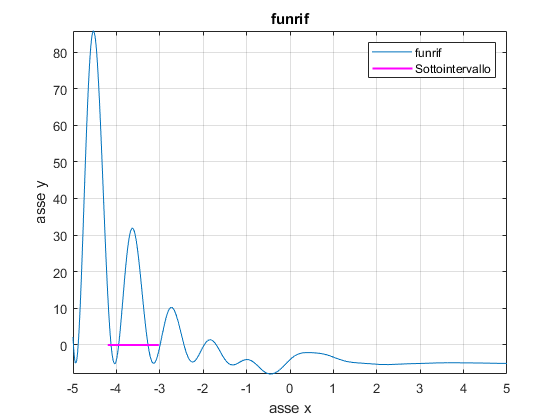

figure(2)
fplot(funrif)
title('funrif')
xlabel('asse x')
ylabel('asse y')
hold on
plot([-4.20 -3.02],[0 0],'k','linewidth',1.5,"Color",'m')
legend('funrif','Sottointervallo')  %utilizzo una leggenda indicativa
hold off
grid on %applico il grigliato tramite il comando grid on.

Finalmente intuisco quale intervallo della funzione meglio rispetta le condizioni delineate dalla traccia riportate anche nel successivo punto 2. Proseguo...

#### 2. visualizzate il grafico della funzione di riferimento in $[a,b]$, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando `text`) gli estremi dell'intervallo scelto, i 3 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *punto di minimo 1*), il secondo valore minimo e l'ascissa del secondo minimo (detta *punto di minimo 2*), il valore massimo e l'ascissa del massimo (detta *punto di massimo*);

Visualizzo il grafico con gli stessi comandi dati precedentemente, facendo attenzione però al plot che in questo caso mi vado definire direttamente per questioni grafiche. Deve contenere, infatti, i valori del sottointervallo che ho scelto, ovvero l'intervallo che ha per estremo sinistro -4.20 e per etremo destro -3.02. Ho scelto tale intervallo poichè la funzione di riferimento risulta avere in questo intervallo, i 3 zeri di riferimento, due minimi e un unico massimo. 

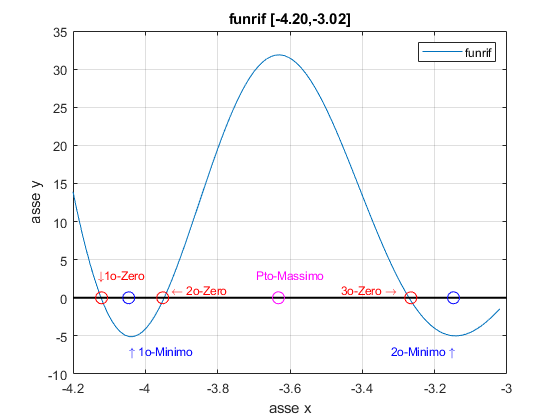

figure(3)
xx = linspace(-4.20,-3.02,100);
yy = funrif(xx);
plot(xx,yy)
title('funrif [-4.20,-3.02]')
xlabel('asse x')
ylabel('asse y')
hold on
plot([-4.20 -3.001],[0 0],'k' ,'linewidth',1.5)
plot((-4.121),(0),'or','markersize',9)
text(-4.131, 3,'\downarrow1o-Zero', "FontSize", 8.7 , "Color", 'r')    %uso il comando text per indicare per sommi capi dove sono presenti gli zeri, minimi e massimo
plot((-3.952),(0),'or','markersize',9)
text(-3.930, 1,'\leftarrow 2o-Zero', "FontSize", 8.7 , "Color", 'r')
plot((-3.266),(0),'or','markersize',9)
text(-3.459, 1,'3o-Zero \rightarrow', "FontSize", 8.7 , "Color", 'r')
text(-4.046, -7,'\uparrow 1o-Minimo', "FontSize", 8.7 , "Color", 'b')
plot((-4.046),(0),'or',"Color",'b','markersize',9)
text(-3.320, -7,'2o-Minimo \uparrow', "FontSize", 8.7 , "Color", 'b')
plot((-3.148),(0),'or',"Color",'b','markersize',9)
text(-4.77, 86.8,'Unico-Massimo \rightarrow', "FontSize", 8.7 , "Color", 'm')
plot((-3.632),(0),'or',"color", 'm' ,'markersize',9)
text(-3.6, 3,'Pto-Massimo',"HorizontalAlignment", "center", "FontSize", 8.7 , "Color", 'm')
legend('funrif')
hold off
grid on

Questo risulta essere il grafico d'interesse, ove sono indicati (a occhio) gli zeri, i due minimi e il massimo. Sottolineo che tali valori sono solo marcati, ma non ancora calcolati, quindi non sono valori con coordinate attendibili.

**3. usate la function Matlab **`fzero`** per determinare i 3 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte; **

Utilizzo come indicato, la function** fzero **chiamandola un numero di volte pari al numero di zeri da calcolare, quindi nel mio caso, tre volte. Passo alla function **fzero** l'intervallo a cui sono interessato per il calcolo dello zero facendo attenzione a dichiarare **format long** in testa, di modo che tutti i risultati abbiano la massima accuratezza delle 16 cifre e, mostro nuovamente il grafico con i comandi precedentemente visti per effettuare le dovute correzioni numeriche al grafico.

format long 
z1 = fzero(funrif, [-4.15 -4.06])

z1 =   -4.122554900509183


z2 = fzero(funrif, [-3.97 -3.91])

z2 =   -3.947782272192532


z3 = fzero(funrif, [-3.30 -3.23])

z3 =   -3.271038052976369


Considero **z1,z2** e **z3 **come soluzioni esatte degli zeri considerati, in quanto come detto in precedenza ottengo il risultato dalla function fzero con accuratezza massima(16 cifre).

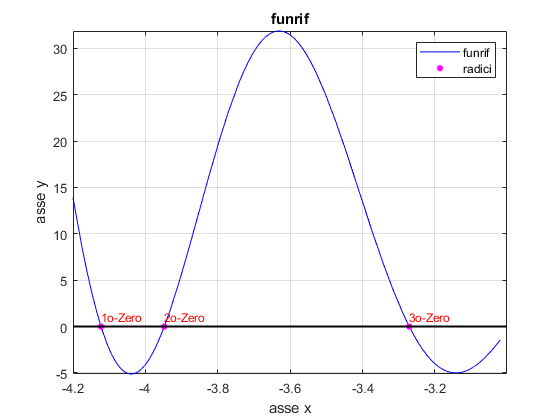

figure(4)
fplot (funrif,[-4.20 -3.02],'b')
title('funrif')
xlabel('asse x')
ylabel('asse y')
hold on
plot((z1),(0),'.m','markersize',15)
text(z1, 1,'1o-Zero', "FontSize", 8.7 , "Color", 'r')
plot((z2),(0),'.m','markersize',15)
text(z2, 1,'2o-Zero', "FontSize", 8.7 , "Color", 'r')
plot((z3),(0),'.m','markersize',15)
text(z3, 1,'3o-Zero', "FontSize", 8.7 , "Color", 'r')
plot([-4.20 -3.001],[0 0],'k','linewidth',1.5)
legend('funrif','radici')
grid on
hold off

**4. determinate un'approssimazione dei 3 zeri, usando il metodo di bisezione (nostra function **`bisezione`**) per lo zero più piccolo, il metodo delle Secanti (nostra function **`Secanti`**) per lo zero centrale e il metodo di Newton (nostra function **`Newton`**) per lo zero più grande (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 3 i casi, che la parte intera e le prime 7 cifre frazionarie siano corrette;**

Per ottenere un'approssimazione dei 3 zeri con parte intera e prime 7 cifre frazionarie corrette, scelgo un valore **delta_ass** appropriato rifacendomi a ciò che è definito nel **teorema sull'errore assoluto**. Il teorema dice che se un dato valore **x **e la sua approssimazione** a**, hanno la stessa parte intera e le stesse prime **m** cifre frazionarie, l'errore assoluto è proprio: **10^(-m)**.   Nel nostro caso quindi il valore del **delta_ass** deve essere **10^(-7)** . Applico quindi i tre metodi tenendo conto di tale considerazione.

1.Uso il metodo di bisezione per lo zero più piccolo, passando alla mia funzione bisezione, la mia funrif, l'intervallo che sto considerando, che ha quindi per estremo sinistro -4.15 e estremo destro -4.06, e il valore di delta_ass, ovvero 10^-7 che in linguaggio matLab si esprime in 1e-7.

bisezione_z1 = bisezione(funrif,-4.15, -4.06, 1e-7)

bisezione_z1 =   -4.122554907798767


Il valore ottenuto dalla function di bisezione coincide con quello della radice del primo zero calcolato in precedenza, ovvero abbiamo ben 8 cifre frazionarie coincidenti.

 2.Uso il metodo delle secanti per il secondo zero ovvero quello in posizione centrale. Gli passo due approssimazioni iniziali poichè tale metodo mi va a sostituire la $f'(x)$ con la pendenza della retta             secante e due punti per il calcolo della correzione cioè la differenza fra le due approssimazioni.

secanti_z2 = Secanti(funrif, -3.97, -3.91, 1e-7, 30)

secanti_z2 =   -3.947782276729540


Il valore ottenuto dalla function di bisezione coincide con quello della radice del primo zero calcolato in precedenza, ovvero abbiamo ben 8 cifre frazionarie coincidenti.

3.Uso il metodo di Newton per il terzo e ultimo zero.

Per usare questo metodo ho bisogno di calcolarmi la $f'(x)$ della mia funzione funrif, pertanto procedo alla scrittura in linguaggio MatLab della $f'(x)$.

funrif_derivata = @(x) (12*cos(2*x))./(3*x.^2 + 1) - sin((7*x)/2 - pi/2).^2.*exp(-x) - (36*x.*sin(2*x))./(3*x.^2 + 1).^2 + 7*cos((7*x)/2 - pi/2).*sin((7*x)/2 - pi/2).*exp(-x); %ricavata da funtool
Newton_z3 = Newton(funrif, funrif_derivata, -3.30, 1e-7, 20 )

Newton_z3 =   -3.271038054134061


Il valore ottenuto dalla function di bisezione coincide con quello della radice del primo zero calcolato in precedenza, abbiamo ben 8 cifre frazionarie coincidenti.

**5. considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle tre approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei tre zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei tre zeri;**

err_ass1 = abs(bisezione_z1-z1)

err_ass1 =      7.289584047498465e-09


err_ass2 = abs(secanti_z2-z2)

err_ass2 =      4.537008102545315e-09


err_ass3 = abs(Newton_z3-z3)

err_ass3 =      1.157691720266030e-09


Tutti valori calcolati rifacendomi alla formula per il calcolo dell'errore assoluto sono minori del delta_ass.

-Calcolo ora i vari residui e rappresento graficamente la funrif per le considerazioni sul tipo di condizionamento del problema.

residuo_1 = abs(funrif(bisezione_z1))

residuo_1 =      9.058333692024689e-07


residuo_2 = abs(funrif(secanti_z2))

residuo_2 =      4.677432725586073e-07


residuo_3 = abs(funrif(Newton_z3))

residuo_3 =      8.947094087830010e-08


Osservo che, i valori sono minori o uguali dell' accuratezza richiesta (delta_ass) nel precedente punto. Riscontriamo quindi, risultati abbastanza precisi, passo successivamente alla rappresentazione grafica e osservando che **il problema è ben condizionato** poichè la funrif nelle vicinanze delle radici ha un andamento verticale che la porta a non "appiattirsi" all'asse x causando poi un problema mal condizioanto.

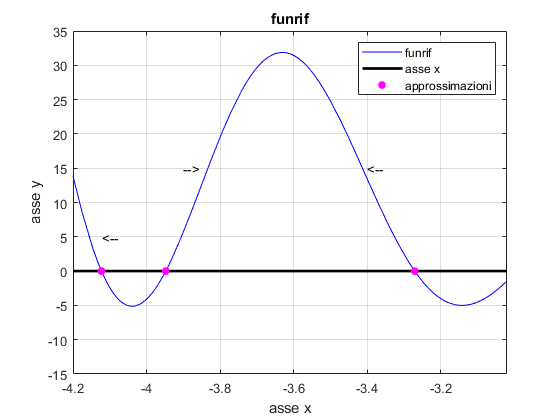

figure(5)
fplot (funrif,[-4.20 -3.02],'b')
title('funrif')
xlabel('asse x')
ylabel('asse y')
hold on
grid on
plot([-4.20 -3.02],[0 0],'k','linewidth',2)
plot(bisezione_z1,0,'.m','markersize',20)
text((-4.12),(5),'<--',"FontSize",10,"Color",'black') %indico l'andamento che assume la funrif
plot(secanti_z2,0,'.m','markersize',20)
text((-3.4),(15),'<--',"FontSize",10,"Color",'black')
plot(Newton_z3,0,'.m','markersize',20)
text((-3.9),(15),'-->',"FontSize",10,"Color",'black')
legend('funrif','asse x','approssimazioni')
axis([-4.20 -3.02 -15 35])
hold off

-Calcolo l'indice di condizionamento per ognuno dei tre zeri (z1,z2,z3)

ind_condiz_1 = (abs(funrif_derivata(z1)))^-1

ind_condiz_1 =    0.008047379037440


ind_condiz_2 = (abs(funrif_derivata(z2)))^-1

ind_condiz_2 =    0.009699782830348


ind_condiz_3 = (abs(funrif_derivata(z3)))^-1

ind_condiz_3 =    0.012939301146868


Con il calcolo dell'indice di condizionamento vado a confermare con i numeri ottenuti, ciò che graficamente possiamo già vedere. Tra indice di condizionamento e problema ben condizionato c'è un rapporto di inversa proporzionalità, si ha cioè che all'aumentare dell'indice aumenta anche il mal condizionamento di un problema, nel nostro caso gli indici di condizionamento per i 3 zeri risulatano essere valori piccoli, molto vicino allo zero di ognuno, pertanto, il problema appare ben condizioanto.

**6. usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e il punto di massimo della vostra funzione di riferimento in **$[a,b]$**, con tre chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e del punto di massimo);**

-Uso la function fminbnd per determinare i due punti di minimo e il punto di massimo della funrif nel sottointervallo scelto inizialmente.

x_min_1 = fminbnd(funrif,-4.2,-4,optimset('TolX',1e-10))

x_min_1 =   -4.039111282353876


x_min_2 = fminbnd(funrif,-3.2,-3,optimset('TolX',1e-10))

x_min_2 =   -3.142282840653547


-Utilizzo ora fminbnd per il calcolo del massimo facendo attenzione però a passare alla fminbnd la -funrif per ottenere il calcolo del massimo e non quello del minimo.

funrif_negata = @(x)-funrif(x);   %nego la funrif, in MathLab possiamo negare una funzione aggiungendo alla stessa il segno meno davanti
x_max = fminbnd(funrif_negata,-3.7,-3.6,optimset('TolX',1e-10))

x_max =   -3.630826300588150


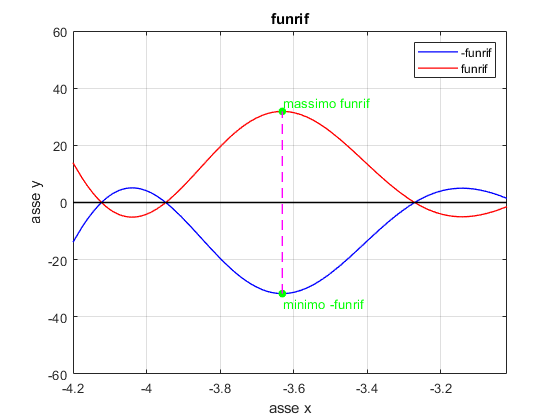

fmin1 = funrif(x_min_1);
fmin2 = funrif(x_min_2);
fmax = funrif(x_max);
fmenomax = funrif_negata(x_max);
figure(6)
fplot(funrif_negata,[-4.20 -3.02],'b',"LineWidth",1)
title('funrif')
xlabel('asse x')
ylabel('asse y')
grid on
hold on
fplot(funrif,[-4.20, -3.02],'r',"LineWidth",1)
plot([x_max x_max],[fmenomax fmax],'.', 'markersize',20, "Color",'g')
plot([x_max x_max],[fmenomax fmax],'--m','LineWidth',1)
text(-3.63, 35, 'massimo funrif','Color','g')
text(-3.63, -35, 'minimo -funrif','Color','g')
plot([-4.20 0],[0 0],'k','linewidth',1.2)
legend('-funrif','funrif')
axis([-4.20, -3.02 -60 60])
hold off

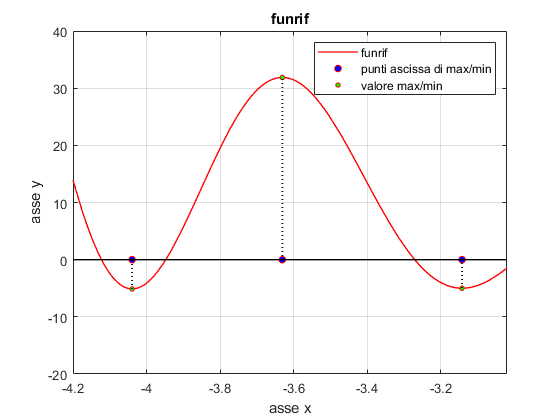

figure(7)
fplot(funrif,[-4.20 -3.02],'r','LineWidth',1)
title('funrif')
xlabel('asse x')
ylabel('asse y')
grid on
hold on
plot([x_min_1 x_max x_min_2], [0 0 0],'or','MarkerSize',5,'MarkerFaceColor','b')
plot([x_min_1 x_max x_min_2], [fmin1 fmax fmin2],'or','MarkerSize',3.5,'MarkerFaceColor','g')
plot([x_min_1 x_min_1],[fmin1 0],':b','MarkerSize',5,"LineWidth",1.3,"Color",'k')
plot([x_min_2 x_min_2],[fmin2 0],':b','MarkerSize',5,"LineWidth",1.3,"Color",'k')
plot([x_max x_max],[0 fmax],':b','MarkerSize',5,"LineWidth",1.3,"Color",'k')
axis([-4.20 -3.02 -20 40])
plot([-4.20 -3.02],[0 0],'k','linewidth',1)
legend('funrif','punti ascissa di max/min','valore max/min')
hold off

**7. verificate che i due punti di minimo e il punto di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando **`axis([xmin xmax ymin ymax])`** ), e usando la **`fzero`** per calcolare gli zeri della derivata; commentate i risultati ottenuti;**

Ricavo la derivata tramite funtool della mia funrif, successivamente applico la function fzero per calcolare gli zeri della derivata di funrif ottenuta con funtool.

x_min1_fzero = fzero(funrif_derivata,-4)

x_min1_fzero =   -4.039111282040272


x_min2_fzero = fzero(funrif_derivata,-3.2)

x_min2_fzero =   -3.142282853384861


x_max_fzero = fzero(funrif_derivata,-3.6)

x_max_fzero =   -3.630826277743392


Adottando la **fzero** nei punti, noto che i risultati sono abbastanza precisi, quello più preciso è x_min_1 che ha ben **9** cifre frazionarie coincidenti, x_min_2 invece ne ha **7**, x_max quello meno preciso, ma comunque abbastanza preciso, ne ha **6**.

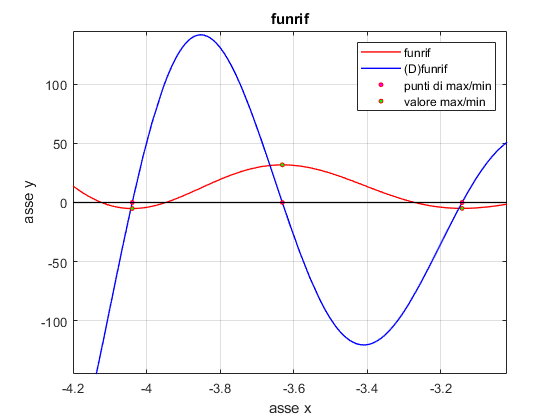

figure(8)
fplot (funrif,[-4.20 -3.02],'r','LineWidth',1)
title('funrif')
xlabel('asse x')
ylabel('asse y')
grid on
hold on
fplot(funrif_derivata,[-4.20 -3.02],'b','LineWidth',1)
plot([x_min_1 x_max x_min_2], [0 0 0],'or','MarkerSize',3,'MarkerFaceColor','m')
plot([x_min_1 x_max x_min_2], [fmin1 fmax fmin2],'or','MarkerSize',3,"MarkerFaceColor",'g')
axis([-4.20 -3.02 -145 145])
plot([-4.20 -3.02],[0 0],'k','linewidth',1)
legend('funrif','(D)funrif','punti di max/min','valore max/min')
hold off

**8. determinate un'approssimazione dei due punti di minimo e del punto di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due minimi , e il metodo di Golden search (nostra function **`fmingolden`**) per il massimo, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 4 cifre frazionarie siano corrette; **

Alle chiamate delle function fminfibo e fmingolden passo un intervallo contenente le soluzioni in lia mia funrif risulta essere unimodale.

fibo_min_1 = fminfibo(funrif,-4.2,-3.9,1e-4)

fibo_min_1 =   -4.039057750759879


fibo_min_2 = fminfibo(funrif,-3.25,-3,1e-4)

fibo_min_2 =   -3.142223910840932


max_golden = fmingolden(funrif_negata,-3.7,-3.5,1e-4)

max_golden =   -3.630833733859427


 I risultati ottenuti sono perfettamente coincidenti fino alla quarta cifra frazionaria, pertanto possiamo dire di aver raggiunto l'accuratezza passata alla function.

**9. considerate l'errore assoluto tra l'approssimazione di Golden search e la corrispondente soluzione esatta e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e tre i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati;**

err_ass_min_1 = abs(x_min_1-fibo_min_1)

err_ass_min_1 =      5.353159399668073e-05


err_ass_min_2 = abs(x_min_2-fibo_min_2)

err_ass_min_2 =      5.892981261501617e-05


err_ass_max_3 = abs(x_max-max_golden)

err_ass_max_3 =      7.433271277168529e-06


I risultati ottenuti dalle tre chiamate, sono tutti inferiori al **delta_ass** scelto precedentemente, pertanto concludo che i risultati ottenuti al precedente punto 8 tramite il metodo di Fibonacci search e Golden search, siano risultati accettabili.